# **Изучение красного смещения звёзд**

close all
clear variables

## Импорт данных

spectra = importdata('spectra.csv');
starNames = importdata('star_names.csv');
lambdaStart = importdata('lambda_start.csv');
lambdaDelta = importdata('lambda_delta.csv');

## Константы

lambdaPr = 656.28; %нм
speedOfLight = 299792.458; %км/c

## Количество звёзд и наблюдений

nObs = size(spectra, 1);
nStars = size(starNames, 1);

## Определение диапазона длин волн

lambdaEnd = lambdaStart + (nObs - 1) * lambdaDelta;
lambda = (lambdaStart : lambdaDelta : lambdaEnd)';

## Подсчёт скорости свет

sHa = zeros(nStars,1);
lambdaHa = zeros(nStars,1);
z = zeros (nStars,1);

for i = 1:nStars
    [sHa(i), index] = min(spectra(:, i));
    lambdaHa(i) = lambda(index);
    z(i) = (lambdaHa(i) / lambdaPr) - 1;
end

speed = z * speedOfLight;

## Построение графика, подсчёт вектора moveaway

fg = figure;
movaway = {};
k = 1;
hold on
for i = 1:nStars
    if speed(i) > 0
        plot(lambda, spectra(:, i), 'LineWidth', 3)
        movaway(k, 1) = starNames(i)
        k = k + 1;
    else
        plot(lambda, spectra(:, i), '--', 'LineWidth', 1)
    end
end

movaway = 1×1 cell array
    {'HD5211'}


movaway = 2×1 cell array
    {'HD5211' }
    {'HD56030'}


movaway = 3×1 cell array
    {'HD5211' }
    {'HD56030'}
    {'HD94028'}


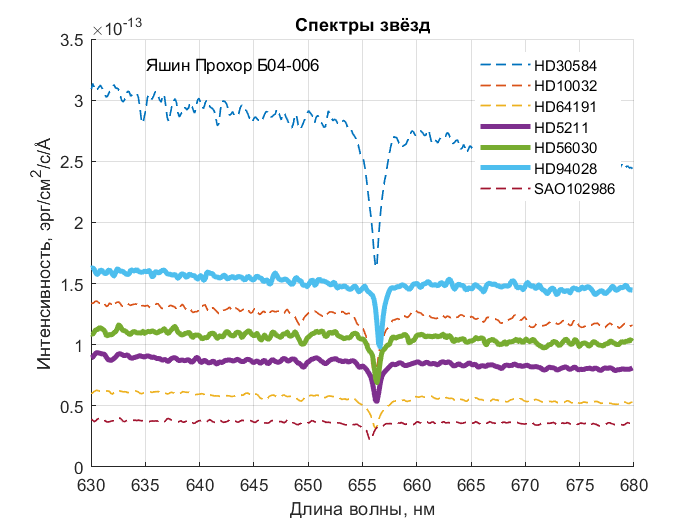

set(fg, 'Visible', 'on')
xlabel('Длина волны, нм')
ylabel(['Интенсивность, эрг/см^2/с/', char(197)])
title('Спектры звёзд')
grid on
legend(starNames)
text(lambdaStart + 5, max(spectra(:, 1)) * 1.05, 'Яшин Прохор Б04-006')
hold off

## Сохранение графика

saveas(fg, 'spectra.png')